clearvars; close all; clc;

# Radiation impedance

2024-04-20, JVsound, J.G. Vermond

## Introduction

This example shows how to calculate and plot the radiation impedance for a rigid circular piston in an infinite baffle.

## Define frequency range

% Frequency in [Hz]:
f       = logspace(1,4,1e3);

% Convert to [rad/s]:
w       = 2*pi * f;

## Create speaker

% Create speaker:
sp      = speaker.woofer;

% Assign Sd value [m2]:
sp.sd   = 1680e-4;

% Request radius of speaker [m]:
sp.a

ans = 0.2312

## Calculate radiation impedance

The specific impedance in $Ns/m^3$ of the air load upon one side of a plane piston mounted in an infinite baffle and vibrating sinusoidally is given by:

$Z_s = \mathbf{R_s}+jX_s$,

where $\mathbf{R_s}$ is the specific radiation resistance in $Ns/m^3$:

$\mathbf{R_s} = \rho_0 c \left(1-\frac{J_1(2ka)}{ka}\right)$,

$X_s$ is the specific radiation reactance in $Ns/m^3$ is given by:

$X_s = \rho_0 c \frac{\mathbf{H_1}(2ka)}{ka}$,

where $J_1$ and $\mathbf{H_1}$ are Bessel and Struve functions respectively. The radiation impedance is than calculated as follows:


$$Z_a = \frac{Z_s}{S_D}$$


The radiation impedance function is a method of the impedance class, which is in the acoustics package.

zarad       = acoustics.impedance.zarad(sp.a,w);

Plot results:

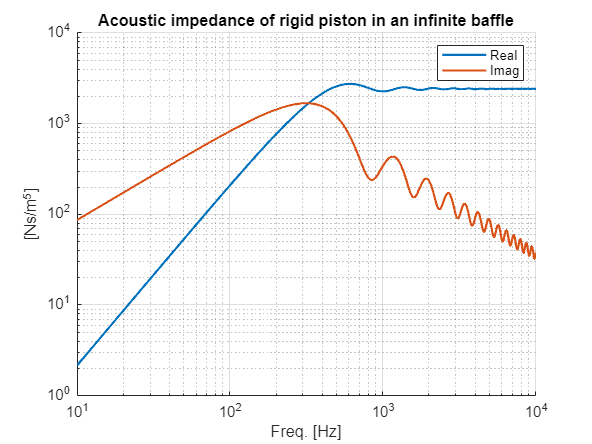

f1          = figure;
ax1         = axes(f1); hold on; grid on;
ax1.XScale  = "log";
ax1.YScale  = "log";

rhoc        = acoustics.misc.rho0 * acoustics.misc.c;

p1          = plot(ax1,f,real(zarad),LineWidth=1.5);
p2          = plot(ax1,f,imag(zarad),LineWidth=1.5);

legend(ax1,[p1 p2],"Real","Imag");

ax1.XLabel.String   = "Freq. [Hz]";
ax1.YLabel.String   = "[Ns/m^5]";
ax1.Title.String    = "Acoustic impedance of rigid piston in an infinite baffle";